# Procedure 1 for Cartpole

Eigenfunctions based on Least-Square

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.3) %linewidh on plots
set(0,'defaultfigurecolor',[1 1 1])

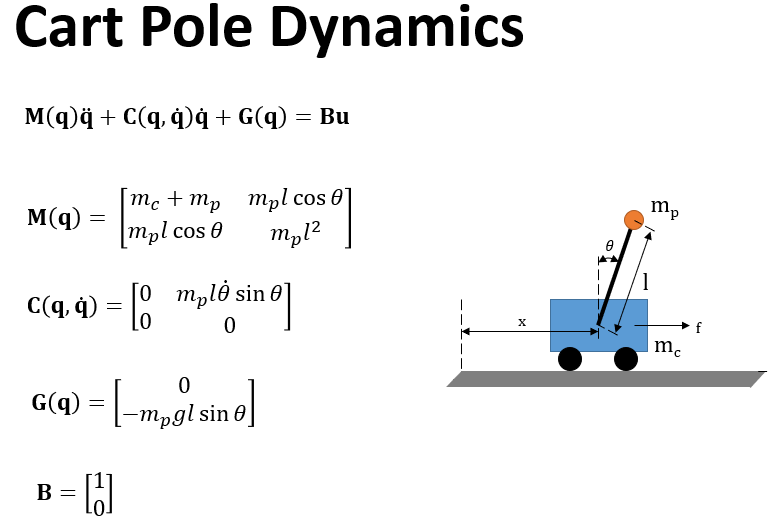

## **Writing this in state space form:**

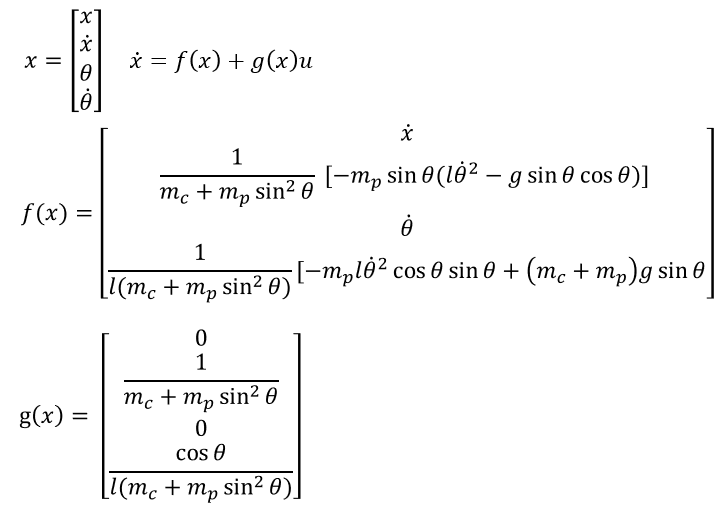

m = 2; M = 8;
l = 0.5; gr = 9.8; 

f = @PendCartModel_F;
g = @PendCartModel_g;

## Parameters setup

n=4; % dimension
Dom = [-2*pi 2*pi]; % Domain
nb_IC = 1e4; %initial coditions

## Linearize system

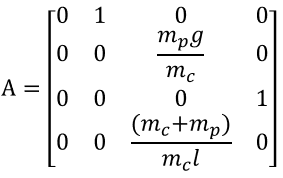    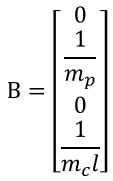

n=4; % dimension
x = sym('x',[n;1]); 
u = sym('u',[1,1]);
x0 = [0;0;0;0];

A = double(subs(jacobian(f(0,x,0),x),x,x0));
B = double(subs(jacobian(f(0,x0,u),u),u,0));

% eps = -0.1;
% A(1,1) = eps;

%A1 = [0 1 0 0; 0 0 m*gr/M 0;0 0 0 1;0 0 (m+M)*gr/(M*l) 0];
%B1 = [0; 1/M; 0; 1/(M*l)];

[V,D1,W1] = eig(A); 

%linear eigenfunctions realization from complex eigenfunctions
[W, D] = cdf2rdf(W1, D1); 

## Selet basis functions to approximate h(x)

deg = 3; %order poly
[Psi, DPsi] = monomial_basis(deg, n);
Nbs = length(Psi);
x1 = sym('x',[n,1]);

Psi = Psi(n+1:end); %remove linear part
Nbs = length(Psi);
DPsi = jacobian(Psi,x1);
Psi = matlabFunction(Psi,'Vars',{x1});
DPsi = matlabFunction(DPsi,'Vars',{x1});

## Solve the least squares problem to estimate U

X = rand(n,nb_IC)*2*Dom(2) - Dom(2);  

E = A;
Ez = E*X; 
G_z = Psi(X); 
F_z = f(0, X, 0); 
Df_z = zeros(Nbs,1);
for i=1:size(X,2)
    Df_z(:,i) = DPsi(X(:,i))*f(0, X(:,i),0);
end

%set low values to zero
Ez(Ez<1e-3)=0;
G_z(G_z<1e-3)=0;
F_z(F_z<1e-3)=0;
Df_z(Df_z<1e-3)=0;


% YALMIP 
U = sdpvar(n,Nbs);
aa=2;
Objective =  norm(U*Df_z + F_z - E*U*G_z - Ez, 'fro') ; %+ aa*norm(U, 'fro'); 
Constraints = [];
opt = sdpsettings('solver','gurobi','verbose',2,'cachesolvers',1);
sol = optimize(Constraints,Objective,opt);

Set parameter Username
Academic license - for non-commercial use only - expires 2022-04-17
Gurobi Optimizer version 9.5.1 build v9.5.1rc2 (win64)
Thread count: 12 physical cores, 24 logical processors, using up to 24 threads
Optimize a model with 40001 rows, 40122 columns and 1332966 nonzeros
Model fingerprint: 0xe56e75fc
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [1e-03, 6e+03]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [6e-05, 2e+02]
Presolve removed 1 rows and 1 columns
Presolve time: 0.26s
Presolved: 40000 rows, 40121 columns, 1332964 nonzeros
Presolved model has 1 second-order cone constraint
Ordering time: 0.04s

Barrier statistics:
 Dense cols : 121
 Free vars  : 120
 AA' NZ     : 1.333e+06
 Factor NZ  : 1.617e+06 (roughly 50 MB of memory)
 Factor Ops : 6.906e+07 (less than 1 second per iteration)
 Threads    : 12

                  Objective                Residual
Ite

hat_h = value(U);

## Eigenfunctions of the original system

%nonlinear eigenfuncitons with scaling
%scale = @(x) x /(Dom(2)-Dom(1));
%Phi = @(x) W'*scale(x) + W'*scale(hat_h*Psi(x));
%DPhi = @(x) W' + W'*scale(hat_h*DPsi(x));

%nonlinear eigenfuncitons without scaling
Phi = @(x) W'*x + W'*hat_h*Psi(x);
DPhi = @(x) W' + W'*hat_h*DPsi(x);

## LQR Controller

% LQR controller
Q = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %cost on states
R = 1; %cost on inputs
[K,P,CLP] = lqr(A,B,Q,R);
P;
uLQR = @(x) -K*x;

## HJ-Koopman Controller:

Where,

% %remove singular part from W and D
newW=W(3:end,3:end); 
newD = D(3:end,3:end);
newB=B(3:end);
hat_R = newW'*(newB*newB')*newW;
W1_inv = inv(newW);
newQ = Q(3:end,3:end);
hat_Q =W1_inv*newQ*W1_inv';
newL = are(newD,hat_R,hat_Q);
L = zeros(4,4);
L(3:end,3:end) = newL;
%L(1:2,1:2) = P(1:2,1:2);
L(1,1)=1;
L(2,2)=2;
uKoop=@(x) -g(0,x)'*DPhi(x)'*L*Phi(x);

% hat_R = W'*(B*B')*W;
% W1_inv = inv(W);
% hat_Q = W1_inv*Q*W1_inv';
% L = are(D,hat_R,hat_Q);
% uKoop=@(x) -g(0,x)'*DPhi(x)'*L*Phi(x);

## Simulation

deltaT = 0.01; %step-time
tspan = 0:deltaT:25; 
options = odeset('RelTol',1e-6,'AbsTol',1e-30);
x_initial = [0;0;0.01;0];

%LQR
[tspan1, xLQR] = ode45(@(t,x) f(t, x, uLQR(x)), tspan, x_initial, options);
if(abs(xLQR(end,3))<=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR succuess


%HJK
[tspan2, x_Koop] = ode45(@(t,x) f(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,3))<=1e-3)
    disp('HJK succuess')
else
    disp('HJK failed')
end

HJK failed


## Plot Results

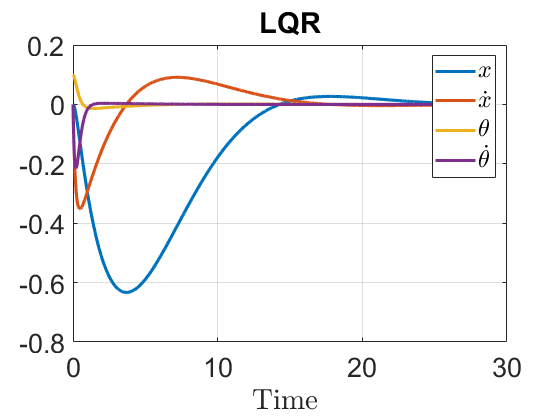

close all
figure(1)
%subplot(2,1,1)
%subplot(2,2,1)
plot(tspan1, xLQR)
grid on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

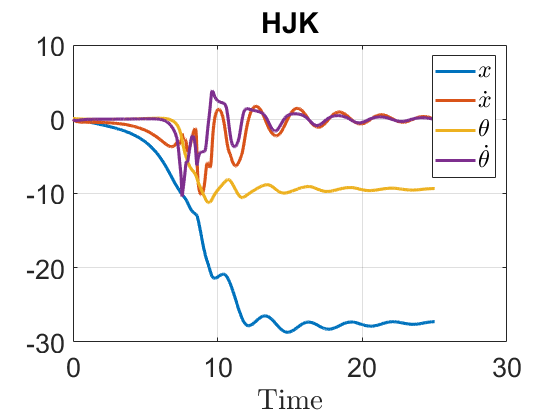

figure(2)
%subplot(2,2,2)
plot(tspan2, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

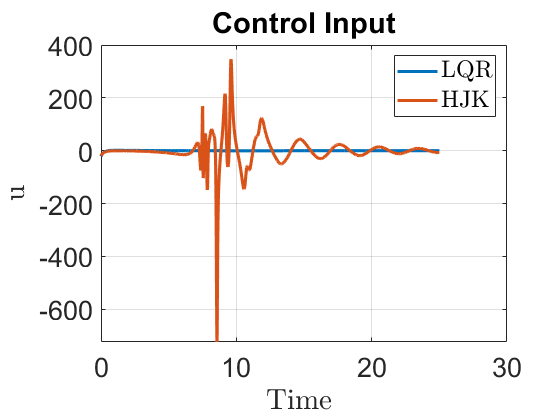

figure(3)
%subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

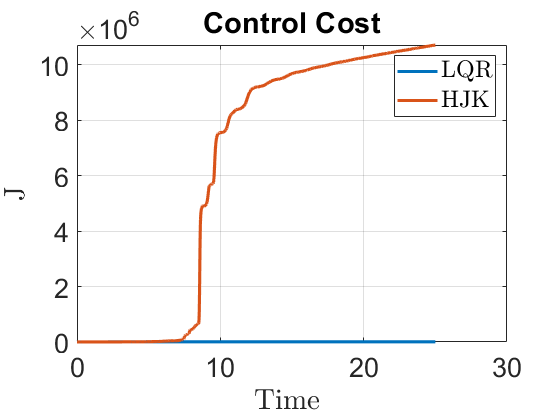

figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2+U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 +U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

%figure(5)

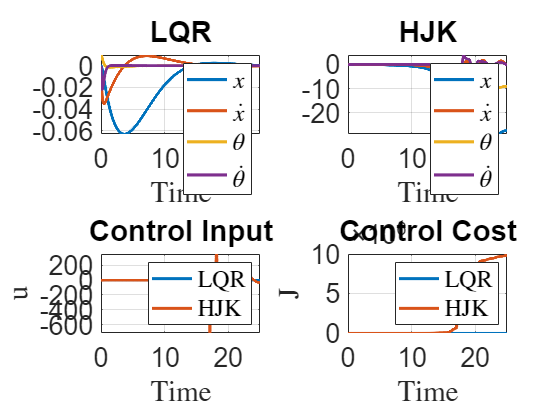

close all
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan2, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2+U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 +U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')